clear

data = readtable("magn_to_calib.csv", "VariableNamingRule","preserve")

data = 574×10 table
    Var1    accX      accY     accZ     gyroX     gyroY     gyroZ     magX     magY    magZ 
    ____    _____    ______    _____    ______    ______    ______    _____    ____    _____

      0     0.204    -0.072    1.007     0.853     0.065    -0.428    -28.8    38.8    -34.5
      1     0.248    -0.062    1.011     0.927    -1.089     1.413    -28.8    38.8    -34.5
      2     0.248    -0.062    1.011     0.927    -1.089     1.413      -28    38.5      -34
      3     0.164    -0.068    1.109     2.454     8.627    11.392      -28    38.5      -34
      4     0.164    -0.068    1.109     2.454     8.627    11.392      -30    37


%% Wczytaj dane z eksperymentu kalibracyjnego
% load('mag3110_20Hz');

B_mierz = [data.("magX"), data.("magY"), data.("magZ")]'

B_mierz =   -28.8000  -28.8000  -28.0000  -28.0000  -30.0000  -30.0000  -30.9000  -30.9000  -31.9000  -31.9000  -31.9000  -34.0000  -34.0000  -34.5000  -34.5000  -34.5000  -34.8000  -34.8000  -35.8000  -35.8000  -35.8000  -35.8000  -35.8000  -36.4000  -36.4000  -36.4000  -36.4000  -35.8000  -35.8000  -35.8000  -36.7000  -36.7000  -35.7000  -35.7000  -35.5000  -35.5000  -35.4000  -35.4000  -35.4000  -36.9000  -36.9000  -36.9000  -35.4000  -35.4000  -36.6000  -36.6000  -35.7000  -35.7000  -35.2000  -35.2000
   38.8000   38.8000   38.5000   38.5000   37.6000   37.6000   35.2000   35.2000   34.3000   34.3000   34.3000   34.2000   34.2000   33.6000   33.6000   33.6000   33.7000   33.7000   34.2000   34.2000   34.2000   33.7000   33.7000   33.6000   33.6000   33.9000   33.9000   34.3000   34.3000   34.3000   33.0000   33.0000   33.6000   33.6000   32.7000   32.7000   32.4000   32.4000   32.4000   32.2000   32.2000   32.2000   33.3000   33.3000   33.3000   33.3000   35.5000   35.5000   36.100

%% Opcje algorytmu
B_ref = 47.31551;        % wartość referencyjna wektora pola magnetycznego w Krakowie [µT]
% B_ref = [mean(train.MagX), mean(train.MagY), mean(train.MagZ)]'
n = size(B_mierz,2);        % sprawdźmy długość wektora mierzonego

Ts = 0.005;

%% Wypisz podstawowe informacje o danych
fprintf('\nCzęstotliwość próbkowania:\t%2.1f [Hz]\n',1/Ts);


Częstotliwość próbkowania:	200.0 [Hz]


fprintf('Liczba próbek: \t\t\t%d\n',n);

Liczba próbek: 			574


fprintf('Czas eksperymentu:\t\t%2.1f [min]\n',n*Ts/60);

Czas eksperymentu:		0.0 [min]



%% Wybierzmy warunek początkowy optymalizacji
C0 = eye(3);                                  % początkowa macierz C
b0 = mean(B_mierz,2);                                % początkowy offset b
x0 = [C0(1,1);C0(2,2);C0(3,3);0;0;0;b0];        % wektor wartości początkowych

%% Dopasujmy optymalizacyjnie bias i macierz skośną
f = @(x)dopasujSfere(x, B_mierz, B_ref);                   % wskaźnik do funkcji celu
options = optimset('TolX', 1e-10, 'MaxFunEvals', 300);  % opcje optymalizacji
[x,fval,exitflag,output] = fminsearch(f,x0,options);    % uruchamiamy algorytm optymalizacji z funkcją celu fitSphere()

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 92.133000 




%% Odzyskaj zoptymalizowaną macierz kalibracyjną i wektor offsetu
% Po optymalizacji otrzymujemy wektor x zawierający prametry znalezionej
% macierzy i wektora kalibracyjnego. Musimy go teraz rozkodować by uzyskać
% ten wektor i macierz
[C, b] = dekodParam(x);

%% Rozkoduj macierz kalibracyjną na wzmocnienia i kąty pomiędzy osiami
Q=C'*C;
k = sqrt(diag(Q));
% Macierz K będzie diagonalna i będzie oznaczać skalę dla każdej z osi
K = diag(k);
% Macierz T będzie w tym przypadku opisywać nieprostopadłość osi, przy czym
% oś Z została wybrana jako ta nieodchylona (którąś musimy wybrać)
T = inv(C*K);           
alpha(1) = 180/pi*acos(T(1,2)*T(2,2) + T(1,3)*T(2,3));
alpha(2) = 180/pi*acos(T(2,3));
alpha(3) = 180/pi*acos(T(1,3));
fprintf('Macierz kalibracji A:\t\t%s\n',mat2str(C));

Macierz kalibracji A:		[0.773995524022995 0.000743364085163084 0.00426195230768561;0 1.0712879561483 0.00290424103033315;0 0 0.828956563456241]


fprintf('Wektor kalibracji b:\t\t%s\n',mat2str(b));

Wektor kalibracji b:		[-18.5799114890772;40.8711493400097;1.80406005655826]


fprintf('Wzmocnienie osi X:\t\t%1.2f\n',k(1));

Wzmocnienie osi X:		0.77


fprintf('Wzmocnienie osi Y:\t\t%1.2f\n',k(2));

Wzmocnienie osi Y:		1.07


fprintf('Wzmocnienie osi Z:\t\t%1.2f\n',k(3));

Wzmocnienie osi Z:		0.83


fprintf('Kąt pomiędzy osią X i Y:\t%3.2f°\n',alpha(1));

Kąt pomiędzy osią X i Y:	90.06°


fprintf('Kąt pomiędzy osią Y i Z:\t%3.2f°\n',alpha(2));

Kąt pomiędzy osią Y i Z:	90.17°


fprintf('Kąt pomiędzy osią X i Z:\t%3.2f°\n',alpha(3));

Kąt pomiędzy osią X i Z:	90.49°


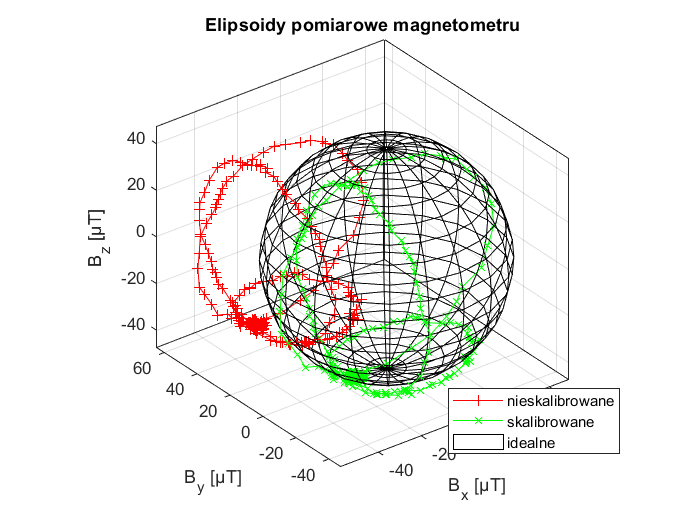


%% Skalibruj pomiar
[B_kal] = kalPomiar(B_mierz, C, b);     % Używamy znalezionych macierzy C i wekotra b do skalibrowania pomiaru

%% Oblicz wartości bezwzględne pomiaru i surowych danych
B_mag = sqrt(sum(B_mierz.^2));                                  % obliczmy wartość bezwzględną surowych pomiarów
B_mag_kal = sqrt(B_kal(1,:).^2+B_kal(2,:).^2+B_kal(3,:).^2);    % obliczmy wartość bezwzględną skalibrowanych pomiarów

%% Kilka obliczeń potrzebnych do testu poprawności rozwiazania
[C_test, b_test] = dekodParam([1; 2; 3; 4; 5; 6; 7; 8; 9]);
B_test = kalPomiar([1,2;3,4;5,6], [1 .1 .1; 0 1.1 0.2; 0 0 1.2], [1;2;3]);

%% Narysujmy sferę pomiarową
figure(), plot3(B_mierz(1,:),B_mierz(2,:),B_mierz(3,:),'+-r');
hold on, grid on;
axis('equal'), box('on');
xlabel('B_x [µT]'), ylabel('B_y [µT]'), zlabel('B_z [µT]');
title('Elipsoidy pomiarowe magnetometru');
plot3(B_kal(1,:), B_kal(2,:), B_kal(3,:), 'x-g');
[xs,ys,zs] = sphere;
sh = surf(B_ref*xs,B_ref*ys,B_ref*zs);
set(sh,'FaceColor',[0 0.1 0],'FaceAlpha',0);
legend('nieskalibrowane', 'skalibrowane', 'idealne', 'Location', 'southeast');

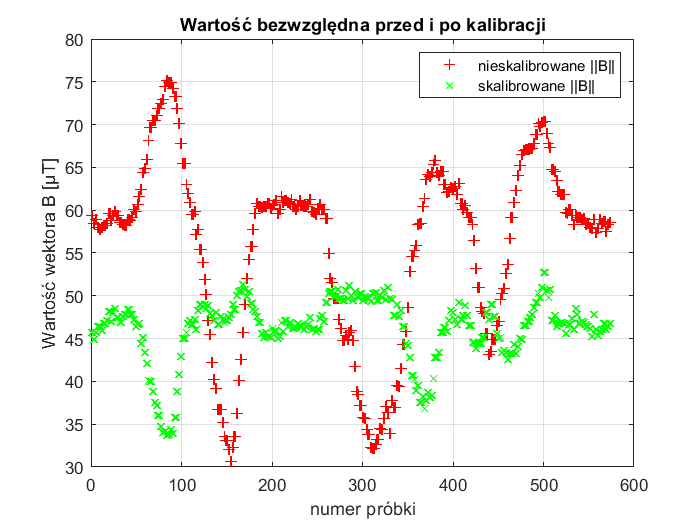


%% Narysujmy wartości bezwzględne skalibrowanego i nieskalibrowanego pomiaru
figure(), plot(B_mag,'r+');
hold on, grid on;
title('Wartość bezwzględna przed i po kalibracji');
xlabel('numer próbki'), ylabel('Wartość wektora B [µT]');
plot(B_mag_kal,'gx');
legend('nieskalibrowane ||B||', 'skalibrowane ||B||');

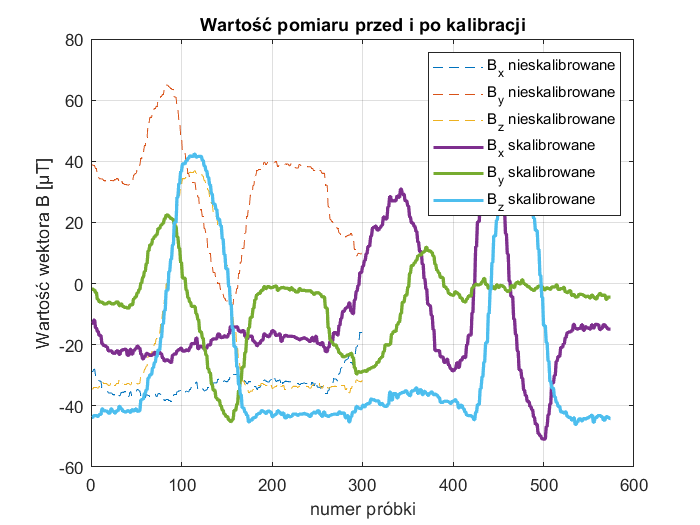


%% Narysujmy wartości skalibrowanego i nieskalibrowanego pomiaru
figure(), plot(B_mierz(:,1:300)','--');
hold on, grid on;
title('Wartość pomiaru przed i po kalibracji');
xlabel('numer próbki'), ylabel('Wartość wektora B [µT]');
plot(B_kal(:,:)','linewidth',2);
legend('B_x nieskalibrowane', 'B_y nieskalibrowane', 'B_z nieskalibrowane', ...
       'B_x skalibrowane', 'B_y skalibrowane', 'B_z skalibrowane');


% zapisywanie do pliku
B_kal

B_kal =   -12.9614  -12.9614  -11.9309  -11.9309  -14.5141  -14.5141  -15.6734  -15.6734  -16.9679  -16.9679  -16.9679  -19.6910  -19.6910  -20.3331  -20.3331  -20.3331  -20.7201  -20.7201  -22.0093  -22.0093  -22.0093  -22.0161  -22.0161  -22.7872  -22.7872  -22.7842  -22.7842  -22.0133  -22.0133  -22.0133  -23.1829  -23.1829  -21.8875  -21.8875  -21.6236  -21.6236  -21.4928  -21.4928  -21.4928  -23.4326  -23.4326  -23.4326  -21.4930  -21.4930  -23.0480  -23.0480  -21.8852  -21.8852  -21.2431  -21.2431
   -1.8146   -1.8146   -2.0963   -2.0963   -2.9364   -2.9364   -5.1760   -5.1760   -6.0178   -6.0178   -6.0178   -6.1160   -6.1160   -6.6745   -6.6745   -6.6745   -6.5808   -6.5808   -6.1124   -6.1124   -6.1124   -6.5827   -6.5827   -6.6741   -6.6741   -6.3925   -6.3925   -6.0210   -6.0210   -6.0210   -7.2385   -7.2385   -6.6764   -6.6764   -7.5142   -7.5142   -7.7936   -7.7936   -7.7936   -7.9813   -7.9813   -7.9813   -6.9532   -6.9532   -6.9555   -6.9555   -4.9009   -4.9009   -4.3425 

T = array2table(B_kal');
T.Properties.VariableNames = {'magX', 'magY', 'magZ'};
% T.Id = [train.Time]
writetable(T, "calibrated_magn.csv")

function [f] = dopasujSfere(x, B_mierz, B_ref)
    [C,b] = dekodParam(x);
    B_kal = kalPomiar(B_mierz, C, b);
    B_mag_kal = sqrt(sum(B_kal.^2));
    f = norm(B_mag_kal - B_ref);                              % Tutaj wpisz swój kod
end

%% Funkcja dekodująca wektor parametrów optymalizowanych x do macierzy C i wekotra b
function [C, b] = dekodParam(x)
    C = [x(1) x(4) x(6); 0 x(2) x(5); 0 0 x(3)];                         % Tutaj wpisz swój kod
    b = x(7:9);
end

%% Funkcja kalibrująca pomiar
function [B_kal] = kalPomiar(B_mierz, C, b)
    B_kal = inv(C) *(B_mierz - b);         % Tutaj wpisz swój kod
end